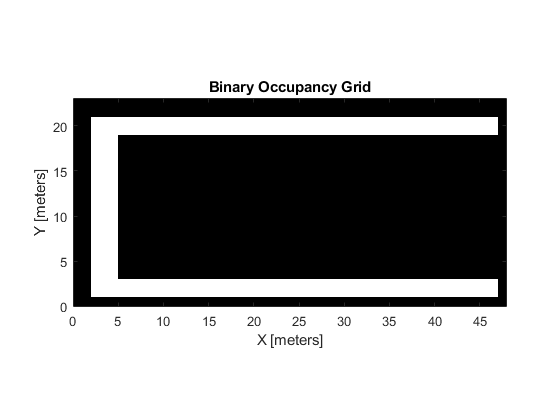

% Load the image
img = imread('C:\Users\frede\OneDrive\Dokumenter\6_semester\ANS\Billede.png');


% Convert the image to grayscale
gray_img = rgb2gray(img);

% Convert the grayscale image to a binary image
binary_img = imbinarize(gray_img);
    
% Create a binary occupancy map from the binary image
map = binaryOccupancyMap(binary_img);

% Resize the map to be 10 times larger
scale_factor = 1/21;
resized_map = imresize(map.occupancyMatrix, scale_factor);

% Create a new binary occupancy map from the resized matrix
new_map = binaryOccupancyMap(resized_map);

% Show the map
show(new_map);

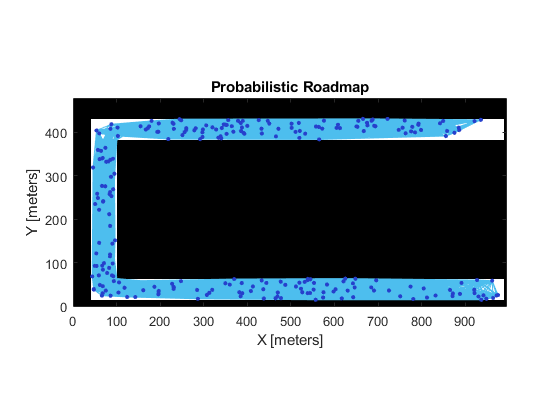

%Create points
prmComplex = mobileRobotPRM(map,250);
show(prmComplex)

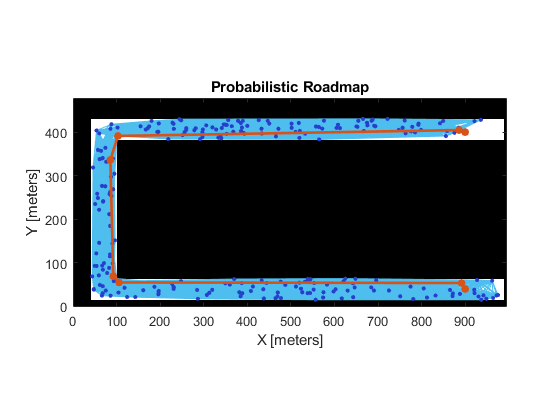

%Define start location
startLocation = [900 400];
endLocation = [900 40];
path = findpath(prmComplex,startLocation,endLocation);
show(prmComplex)